clear, close all, clc

Et eksperiment beskriver mængden af radon, der udfældes i et bad i procent, når brusehovedets åbninger har forskellige diametre.

load('dataset_problem_13_10.mat')

Der er fire observationer per faktor-niveau, og i alt seks faktor-niveauer.

n = 4

n = 4

a = 6

a = 6

N = a*n

N = 24

Opgave a og b) Påvirker åbningens størrelse mængden af radon, der udfældes? Anvend gennemsnittet af procenterne. Brug α = 0,01.

Find P-værdien.

alpha = 0.01;

Y1 = data(:,1);
Y2 = data(:,2);
Y3 = data(:,3);
Y4 = data(:,4);
Y5 = data(:,5);
Y6 = data(:,6);

Y1bar = 1/n * sum(Y1)

Y1bar = 82.7500

Y2bar = 1/n * sum(Y2)

Y2bar = 77

Y3bar = 1/n * sum(Y3)

Y3bar = 75

Y4bar = 1/n * sum(Y4)

Y4bar = 71.7500

Y5bar = 1/n * sum(Y5)

Y5bar = 65

Y6bar = 1/n * sum(Y6)

Y6bar = 62.7500


Yallbar = 1/(N) * (sum(Y1)+sum(Y2)+sum(Y3)+sum(Y4)+sum(Y5)+sum(Y6))

Yallbar = 72.3750

Ybars = [Y1bar Y2bar Y3bar Y4bar Y5bar Y6bar];


SST = 0;
for i = 1:a
    for j = 1:n
        SST = SST + (data(j,i)-Yallbar)^2;
    end
end
SST

SST = 1.2656e+03


SSW = 0;
for i = 1:a
    for j = 1:n
        SSW = SSW + (data(j,i)-Ybars(1,i))^2;
    end
end
SSW

SSW = 132.2500


SSB = 0;
for i = 1:a
    SSB = SSB + n*(Ybars(1,i)-Yallbar)^2;
end
SSB

SSB = 1.1334e+03


S_T_squared = SST/(N-1)

S_T_squared = 55.0272

S_W_squared = SSW/(N-a)

S_W_squared = 7.3472

S_B_squared = SSB/(a-1)

S_B_squared = 226.6750


f0 = S_B_squared/S_W_squared

f0 = 30.8518


P = 1 - fcdf(f0, a-1, N-a)

P = 3.1595e-08

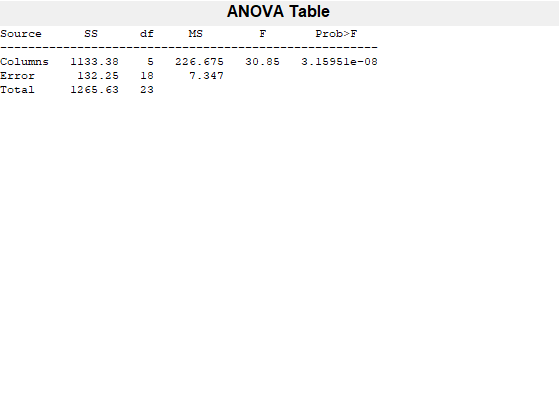

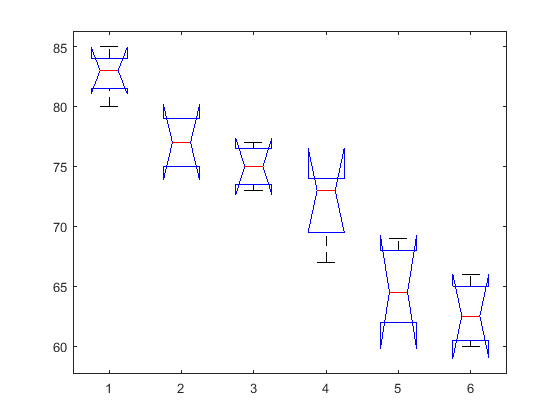

ans = 3.1595e-08


% Det er altså ekstremt usandsynligt
% Nulhypotesen forkastes derfor, og den alternative
% hypotese, at middelværdierne er forskellige, accepteres

% Alternativ metode:
anova1(data)

Opgave c) Analyser residualerne for eksperimentet.

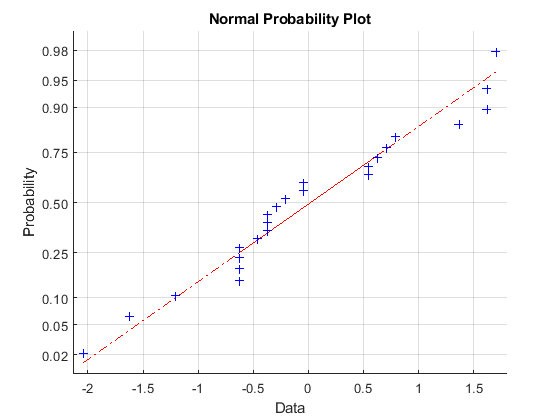

R = ANOVAResiduals(data);
np = [R(:,1);R(:,2);R(:,3);R(:,4);R(:,5);R(:,6)];
normplot(np)

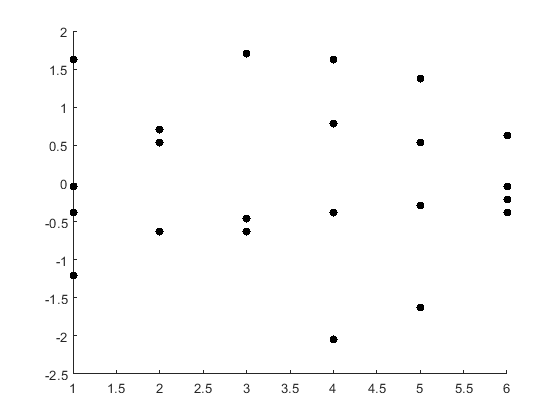

figure(3)
hold on
sz = size(R(:,1));
scatter(ones(sz),R(:,1),'filled','k')
scatter(2*ones(sz),R(:,2),'filled','k')
scatter(3*ones(sz),R(:,3),'filled','k')
scatter(4*ones(sz),R(:,4),'filled','k')
scatter(5*ones(sz),R(:,5),'filled','k')
scatter(6*ones(sz),R(:,6),'filled','k')


% Residualerne virker helt fine

Opgave d) Find et 95%-konfidensinterval på middelværdien af procent radon udfældet, når diameteren er 1,99 (det sjette faktor-niveau).

alpha = 0.05;
% Udregnes med: Y_i_bar +- sqrt(SW^2/n_i)*t_N-a,alpha/2
U = Y6bar + sqrt(S_W_squared/n) * tinv(1-alpha/2,N-a)

U = 65.5974

L = Y6bar + sqrt(S_W_squared/n) * tinv(alpha/2,N-a)

L = 59.9026